# **Task_02:   **Design Multi Tuned Mass Dampers (MTMDs)

In this task we'll develop the equations of motion of the system shown below - it's just our standard 3-dof system where each primary mass $\left(m_1 ,m_2 ,m_3 \right)$ has an attached secondary mass and stiffness.  These secondary masses and stiffnesses are our **Tuned Mass Dampers (TMDs)**.  So consider the system shown below:

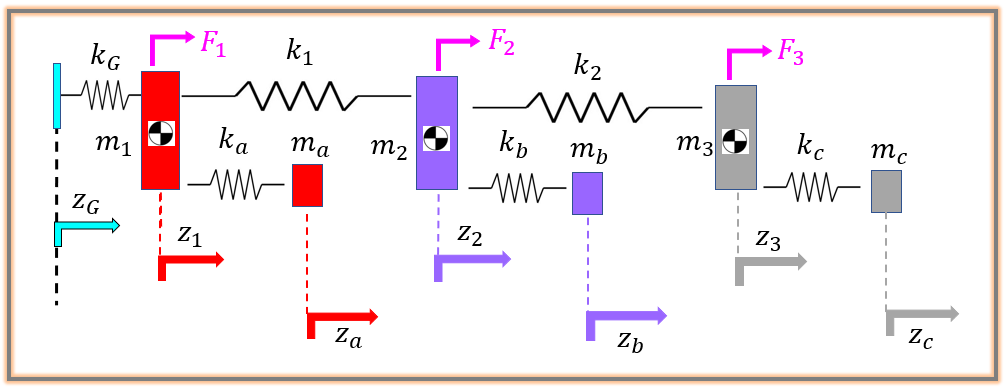

## Clear your workspace:

clear

Define some Symbolic variables:

syms m_1   m_2   m_3   m_a   m_b   m_c
syms k_1   k_2         k_a   k_b   k_c  k_g
syms F_1   F_2   F_3

syms      z_1        z_2        z_3        z_a        z_b        z_c   z_g
syms z_ddot_1   z_ddot_2   z_ddot_3   z_ddot_a   z_ddot_b   z_ddot_c  
syms  z_dot_1    z_dot_2    z_dot_3    z_dot_a    z_dot_b    z_dot_c  z_dot_g

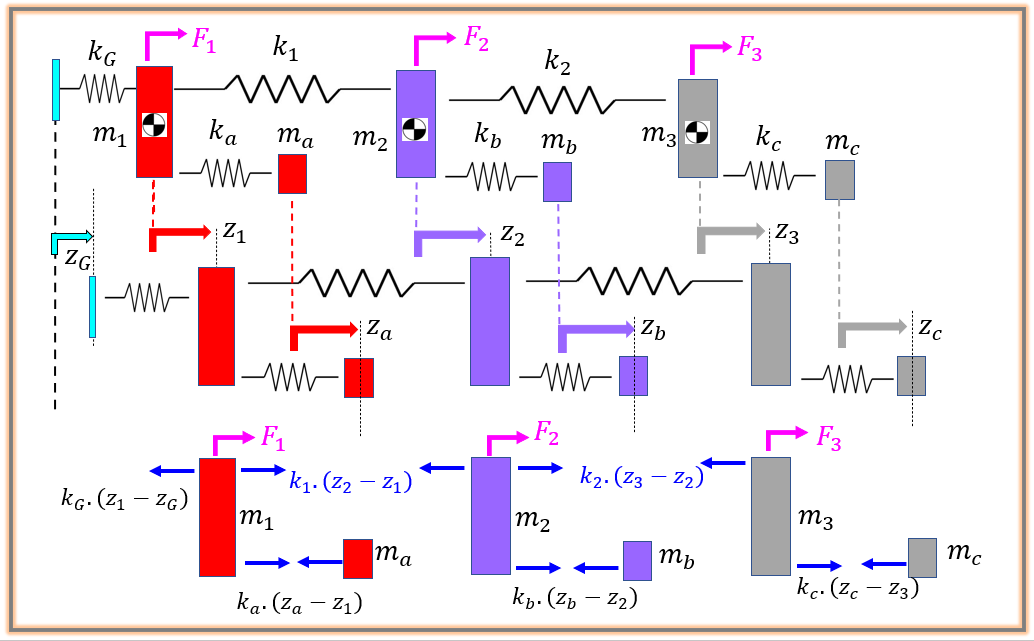

Apply Newton's 2nd Law to each mass:   $m\ldotp a=\sum F_i$

- 
$$m_1 \ldotp {\ddot{z} }_1 \;\;=\;F_1 \;-\;k_G \ldotp \left(z_1 -z_G \right)\;+\;\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;\;+\;\;k_a \ldotp \left(z_a -z_1 \right)$$


- 
$$m_2 \ldotp {\ddot{z} }_2 \;\;=\;F_2 \;-\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;\;+\;\;\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;+\;\;k_b \ldotp \left(z_b -z_2 \right)\;\;$$


- 
$$m_3 \ldotp {\ddot{z} }_3 \;\;=\;F_3 \;-\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;\;+\;\;k_c \ldotp \left(z_c -z_3 \right)\;\;\;\;$$


- 
$$m_a \ldotp {\ddot{z} }_a \;\;=\;\;\;\;\;\;-\;k_a \ldotp \left(z_a -z_1 \right)\;$$


- 
$$m_b \ldotp {\ddot{z} }_b \;\;=\;\;\;\;\;\;-\;k_b \ldotp \left(z_b -z_2 \right)\;$$


- 
$$m_c \ldotp {\ddot{z} }_c \;\;=\;\;\;\;\;\;-\;k_c \ldotp \left(z_c -z_3 \right)\;$$


EQ_EOM_NO_damping = ...
         [ m_1*z_ddot_1 == F_1 - k_g*(z_1-z_g) + k_1*(z_2-z_1) + k_a*(z_a-z_1);
           m_2*z_ddot_2 == F_2 - k_1*(z_2-z_1) + k_2*(z_3-z_2) + k_b*(z_b-z_2);
           m_3*z_ddot_3 == F_3 - k_2*(z_3-z_2) +                 k_c*(z_c-z_3);
           m_a*z_ddot_a ==     - k_a*(z_a-z_1);
           m_b*z_ddot_b ==     - k_b*(z_b-z_2);
           m_c*z_ddot_c ==     - k_c*(z_c-z_3);
         ]

$$EQ\_EOM\_NO\_damping = \left(\begin{array}{c} m_{1}\,{\ddot{z}}_{1}=F_{1}-k_{1}\,\left(z_{1}-z_{2}\right)-k_{a}\,\left(z_{1}-z_{a}\right)-k_{g}\,\left(z_{1}-z_{g}\right)\\ m_{2}\,{\ddot{z}}_{2}=F_{2}+k_{1}\,\left(z_{1}-z_{2}\right)-k_{2}\,\left(z_{2}-z_{3}\right)-k_{b}\,\left(z_{2}-z_{b}\right)\\ m_{3}\,{\ddot{z}}_{3}=F_{3}+k_{2}\,\left(z_{2}-z_{3}\right)-k_{c}\,\left(z_{3}-z_{c}\right)\\ m_{a}\,{\ddot{z}}_{a}=k_{a}\,\left(z_{1}-z_{a}\right)\\ m_{b}\,{\ddot{z}}_{b}=k_{b}\,\left(z_{2}-z_{b}\right)\\ m_{c}\,{\ddot{z}}_{c}=k_{c}\,\left(z_{3}-z_{c}\right) \end{array}\right)$$

### Now collect equations and extract $M,K,F$:

We know that our system equations of motion can be written in the form:

- $M\ldotp \ddot{x} \;+\;K\ldotp x=\;F$     where   $x\in R^{\;6\times 1}$     and       $x^T =\left\lbrack \begin{array}{ccccccc}
\;\;z_1  & z_2  & z_3  & z_a  & z_b  & z_c  & 
\end{array}\right\rbrack$

We can rewrite this equation as a "mega" equation of the form:

- $\left\lbrack \begin{array}{ccc}
M &  & K
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\;\ddot{x} \;\\
x
\end{array}\right\rbrack =\;F$     $\Longrightarrow$     $A\;\ldotp z=b$      where   $z\in R^{\;12\times 1}$   and   $A\;=\left\lbrack M\;\;\;K\right\rbrack \;\in R^{\;6\times 12}$

The [`equationsToMatrix()`](matlab:  web(fullfile(docroot, 'symbolic/sym.equationstomatrix.html'))) function will rearrange our 7 equations of motion into this $A\;\ldotp Z=b$  form:

my_z_vars = [ z_ddot_1,  z_ddot_2,  z_ddot_3,  z_ddot_a,  z_ddot_b,  z_ddot_c,  ...
                   z_1,       z_2,       z_3,       z_a,       z_b,       z_c ];   
    
[A, b]    = equationsToMatrix(EQ_EOM_NO_damping, my_z_vars);   

Now extract $M,K,F$:

M_full = A(:,1:6)

$$M\_full = \left(\begin{array}{cccccc} m_{1} & 0 & 0 & 0 & 0 & 0\\ 0 & m_{2} & 0 & 0 & 0 & 0\\ 0 & 0 & m_{3} & 0 & 0 & 0\\ 0 & 0 & 0 & m_{a} & 0 & 0\\ 0 & 0 & 0 & 0 & m_{b} & 0\\ 0 & 0 & 0 & 0 & 0 & m_{c} \end{array}\right)$$

K_full = A(:,7:end)

$$K\_full = \left(\begin{array}{cccccc} k_{1}+k_{a}+k_{g} & -k_{1} & 0 & -k_{a} & 0 & 0\\ -k_{1} & k_{1}+k_{2}+k_{b} & -k_{2} & 0 & -k_{b} & 0\\ 0 & -k_{2} & k_{2}+k_{c} & 0 & 0 & -k_{c}\\ -k_{a} & 0 & 0 & k_{a} & 0 & 0\\ 0 & -k_{b} & 0 & 0 & k_{b} & 0\\ 0 & 0 & -k_{c} & 0 & 0 & k_{c} \end{array}\right)$$

F_full = b

$$F\_full = \left(\begin{array}{c} F_{1}+k_{g}\,z_{g}\\ F_{2}\\ F_{3}\\ 0\\ 0\\ 0 \end{array}\right)$$

### Incorporate Damping - Part 1

The damping matrix will have the same pattern as the stiffness matrix (i.e.: where there is stiffness there is an associated damper)

syms c_1   c_2    c_a   c_b   c_c  c_g

C_full = subs(K_full, [k_1   k_2   k_a   k_b   k_c  k_g], ...
                      [c_1   c_2   c_a   c_b   c_c  c_g]     )

$$C\_full = \left(\begin{array}{cccccc} c_{1}+c_{a}+c_{g} & -c_{1} & 0 & -c_{a} & 0 & 0\\ -c_{1} & c_{1}+c_{2}+c_{b} & -c_{2} & 0 & -c_{b} & 0\\ 0 & -c_{2} & c_{2}+c_{c} & 0 & 0 & -c_{c}\\ -c_{a} & 0 & 0 & c_{a} & 0 & 0\\ 0 & -c_{b} & 0 & 0 & c_{b} & 0\\ 0 & 0 & -c_{c} & 0 & 0 & c_{c} \end{array}\right)$$

### Incorporate Damping - Part 2

We need to add the damping force associated with the $k_G$ spring that acts on mass $m_1$

F_full(1,1) = F_full(1,1)  +   c_g*z_dot_g;

So the full force vector is now:

F_full

$$F\_full = \left(\begin{array}{c} F_{1}+c_{g}\,{\dot{z}}_{g}+k_{g}\,z_{g}\\ F_{2}\\ F_{3}\\ 0\\ 0\\ 0 \end{array}\right)$$

### So Equations of Motion are:

- $M\ldotp \ddot{x} \;\;\;+\;\;C\ldotp \dot{x} \;\;+\;\;K\ldotp x\;\;=\;F$     where   $x\in R^{\;6\times 1}$     and       $x^T =\left\lbrack \begin{array}{ccccccc}
\;\;z_1  & z_2  & z_3  & z_a  & z_b  & z_c  & 
\end{array}\right\rbrack$

### Simulink prework - Solve for Accelerations:

Soon we'll create convert our system ODEs into a Simulink block. So define the array of the dof accelerations

- 
$$\ddot{x} \;\;=M^{-1} \ldotp \left(F-C\ldotp \dot{x} -K\ldotp x\right)$$


POS_DOF_COL = [      z_1        z_2        z_3        z_a        z_b        z_c  ].';
VEL_DOF_COL = [  z_dot_1    z_dot_2    z_dot_3    z_dot_a    z_dot_b    z_dot_c  ].';
ACC_DOF_COL = [ z_ddot_1   z_ddot_2   z_ddot_3   z_ddot_a   z_ddot_b   z_ddot_c  ].';

%EQ_EOM = M_full*ACC_DOF_COL  +  C_full*VEL_DOF_COL  + K_full*POS_DOF_COL == F_full;
ACC_SOL = inv(M_full)*(F_full - C_full*VEL_DOF_COL - K_full*POS_DOF_COL)

$$ACC\_SOL = \left(\begin{array}{c} \frac{F_{1}+c_{1}\,{\dot{z}}_{2}+c_{a}\,{\dot{z}}_{a}+c_{g}\,{\dot{z}}_{g}+k_{1}\,z_{2}+k_{a}\,z_{a}+k_{g}\,z_{g}-{\dot{z}}_{1}\,\left(c_{1}+c_{a}+c_{g}\right)-z_{1}\,\left(k_{1}+k_{a}+k_{g}\right)}{m_{1}}\\ \frac{F_{2}+c_{1}\,{\dot{z}}_{1}+c_{2}\,{\dot{z}}_{3}+c_{b}\,{\dot{z}}_{b}+k_{1}\,z_{1}+k_{2}\,z_{3}+k_{b}\,z_{b}-{\dot{z}}_{2}\,\left(c_{1}+c_{2}+c_{b}\right)-z_{2}\,\left(k_{1}+k_{2}+k_{b}\right)}{m_{2}}\\ \frac{F_{3}-z_{3}\,\left(k_{2}+k_{c}\right)+c_{2}\,{\dot{z}}_{2}+c_{c}\,{\dot{z}}_{c}+k_{2}\,z_{2}+k_{c}\,z_{c}-{\dot{z}}_{3}\,\left(c_{2}+c_{c}\right)}{m_{3}}\\ \frac{c_{a}\,{\dot{z}}_{1}-c_{a}\,{\dot{z}}_{a}+k_{a}\,z_{1}-k_{a}\,z_{a}}{m_{a}}\\ \frac{c_{b}\,{\dot{z}}_{2}-c_{b}\,{\dot{z}}_{b}+k_{b}\,z_{2}-k_{b}\,z_{b}}{m_{b}}\\ \frac{c_{c}\,{\dot{z}}_{3}-c_{c}\,{\dot{z}}_{c}+k_{c}\,z_{3}-k_{c}\,z_{c}}{m_{c}} \end{array}\right)$$

### Simulink prework - And create a Simulink block

tf_i_should_create_SL_block = true;

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_acc';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_acc'], ...
                         ACC_SOL,     ...
                        'Outputs',  {'Acc'},  ...
                        'Optimize', false );
                    
    % make the block a YELLOW color
    set_param([MODEL_NAME,'/my_acc'],'BackgroundColor','[1, 1, 0.607843]')
end

## Frequency Response Function(FRF) Analysis

Consider the **UNdamped** homogeneous system:

- $M\ldotp \ddot{x} \;+\;K\ldotp x=F$  where $X\;\in R^{\;N\times 1}$

Taking the Laplace transform AND assuming zero initial conditions, we have

- 
$$\left\lbrack M\ldotp s^2 \;\;+\;\;K\right\rbrack \ldotp X\left(s\right)\;=F\left(s\right)$$


And the FRF is obtained via $s=j\ldotp \omega$

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp X\left(\omega \right)\;=F\left(\omega \right)$$


-             
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;X\left(\omega \right)\;={\left\lbrack -M\ldotp \omega^2 \;+\;K\right\rbrack }^{-1} \ldotp F\left(\omega \right)$$


-                            
$$X\left(\omega \right)=H\left(\omega \right)\ldotp F\left(\omega \right)$$


 **WARNING**:  The $H\left(\omega \right)$ matrix contains alot of terms and "echoing/displaying the complete matrix really "grinds" the editor down (e.g.: the editor becomes very sluggish).  So don't do that - we'll echo a selection of $H\left(\omega \right)$ next.

syms omega
tic;
H = inv( -M_full*omega^2 + K_full );
H = simplify(H);
toc

Elapsed time is 6.580062 seconds.


whos H

  Name      Size            Bytes  Class    Attributes

  H         6x6                 8  sym                



For clarity, let's assume the following:

- 
$$F_1 =F_2 =F_3 =0$$


- 
$$F_{1G} =k_G \ldotp z_G$$


And let's write out these Transfer function arrays and matrices in full - NOTE:  I will use the symbol $\otimes$ to indicate "I'm NOT interested"  .... because there is ZERO applied force at these dof.

- 
$$\left\lbrack \begin{array}{c}
Z_1 \left(\omega \right)\\
Z_2 \left(\omega \right)\\
Z_3 \left(\omega \right)\\
Z_a \left(\omega \right)\\
Z_b \left(\omega \right)\\
Z_c \left(\omega \right)
\end{array}\right\rbrack \;=\;\left\lbrack \begin{array}{cccccc}
H_{11}  & \otimes  & \otimes  & \otimes  & \otimes  & \otimes \\
H_{21}  & \otimes  & \otimes  & \otimes  & \otimes  & \otimes \\
H_{31}  & \otimes  & \otimes  & \otimes  & \otimes  & \otimes \\
H_{\mathrm{a1}}  & \otimes  & \otimes  & \otimes  & \otimes  & \otimes \\
H_{\mathrm{b1}}  & \otimes  & \otimes  & \otimes  & \otimes  & \otimes \\
H_{\mathrm{c1}}  & \otimes  & \otimes  & \otimes  & \otimes  & \otimes 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
F_{1g} \\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
H_{11} \\
H_{21} \\
H_{31} \\
H_{\mathrm{a1}} \\
H_{\mathrm{b1}} \\
H_{\mathrm{c1}} 
\end{array}\right\rbrack \ldotp F_{1G}$$


So:

- $\left\lbrack \begin{array}{c}
Z_1 \left(\omega \right)\\
Z_2 \left(\omega \right)\\
Z_3 \left(\omega \right)\\
Z_a \left(\omega \right)\\
Z_b \left(\omega \right)\\
Z_c \left(\omega \right)
\end{array}\right\rbrack \;=\;\;\;\left\lbrack \begin{array}{c}
H_{11} \\
H_{21} \\
H_{31} \\
H_{\mathrm{a1}} \\
H_{\mathrm{b1}} \\
H_{\mathrm{c1}} 
\end{array}\right\rbrack \ldotp F_{1G}$      where   $F_{1G} =k_G \ldotp z_G$

So let's ONLY focus on the first column of $H\left(\omega \right)$

H_col = H(:,1);
H_col = simplify(H_col);

What are the NUMERATORS of the transfer functions $H_{11}$, $H_{21}$ , $H_{31}$:

[num_col, den_col] = numden(H_col(1:3));
num_col

$$num\_col = \left(\begin{array}{c} -\left(k_{a}-m_{a}\,\omega^{2}\right)\,\left(k_{1}\,k_{2}\,k_{b}\,k_{c}-k_{1}\,k_{2}\,k_{b}\,m_{c}\,\omega^{2}-k_{1}\,k_{2}\,k_{c}\,m_{b}\,\omega^{2}-k_{1}\,k_{b}\,k_{c}\,m_{3}\,\omega^{2}-k_{2}\,k_{b}\,k_{c}\,m_{2}\,\omega^{2}-k_{2}\,k_{b}\,k_{c}\,m_{3}\,\omega^{2}-k_{2}\,k_{b}\,k_{c}\,m_{b}\,\omega^{2}-k_{1}\,k_{b}\,k_{c}\,m_{c}\,\omega^{2}-k_{2}\,k_{b}\,k_{c}\,m_{c}\,\omega^{2}+k_{1}\,k_{2}\,m_{b}\,m_{c}\,\omega^{4}+k_{1}\,k_{b}\,m_{3}\,m_{c}\,\omega^{4}+k_{1}\,k_{c}\,m_{3}\,m_{b}\,\omega^{4}+k_{2}\,k_{b}\,m_{2}\,m_{c}\,\omega^{4}+k_{2}\,k_{c}\,m_{2}\,m_{b}\,\omega^{4}+k_{2}\,k_{b}\,m_{3}\,m_{c}\,\omega^{4}+k_{2}\,k_{c}\,m_{3}\,m_{b}\,\omega^{4}+k_{b}\,k_{c}\,m_{2}\,m_{3}\,\omega^{4}+k_{2}\,k_{b}\,m_{b}\,m_{c}\,\omega^{4}+k_{b}\,k_{c}\,m_{3}\,m_{b}\,\omega^{4}+k_{1}\,k_{c}\,m_{b}\,m_{c}\,\omega^{4}+k_{2}\,k_{c}\,m_{b}\,m_{c}\,\omega^{4}+k_{b}\,k_{c}\,m_{2}\,m_{c}\,\omega^{4}+k_{b}\,k_{c}\,m_{b}\,m_{c}\,\omega^{4}-k_{1}\,m_{3}\,m_{b}\,m_{c}\,\omega^{6}-k_{2}\,m_{2}\,m_{b}\,m_{c}\,\omega^{6}-k_{2}\,m_{3}\,m_{b}\,m_{c}\,\omega^{6}-k_{b}\,m_{2}\,m_{3}\,m_{c}\,\omega^{6}-k_{c}\,m_{2}\,m_{3}\,m_{b}\,\omega^{6}-k_{b}\,m_{3}\,m_{b}\,m_{c}\,\omega^{6}-k_{c}\,m_{2}\,m_{b}\,m_{c}\,\omega^{6}+m_{2}\,m_{3}\,m_{b}\,m_{c}\,\omega^{8}\right)\\ k_{1}\,\left(k_{a}-m_{a}\,\omega^{2}\right)\,\left(k_{b}-m_{b}\,\omega^{2}\right)\,\left(k_{2}\,m_{c}\,\omega^{2}-k_{2}\,k_{c}+k_{c}\,m_{3}\,\omega^{2}+k_{c}\,m_{c}\,\omega^{2}-m_{3}\,m_{c}\,\omega^{4}\right)\\ -k_{1}\,k_{2}\,\left(k_{a}-m_{a}\,\omega^{2}\right)\,\left(k_{b}-m_{b}\,\omega^{2}\right)\,\left(k_{c}-m_{c}\,\omega^{2}\right) \end{array}\right)$$

 **Pause and Ponder:**

- The numerator of $H_{11} \left(\omega \right)$ appears to be a 10th order polynomial ... so finding the ANALYTIC roots for this is tough.

- But, the symbolic engine has been able to determine that it contains a $\left(k_a -m_a \ldotp \omega^2 \right)$ term.

- So it looks like the "classic" vibration Absorber formula is also applicable for this M-dof system, i.e.:

- 
$$k_{\mathrm{ABS}} \;\;=\;m_{\mathrm{ABS}} \ldotp {\omega_{\mathrm{DES}} }^2$$


Also, note the following

- 
$$H_{11} \left(s\right)\;\;\mathrm{numerator}\;\mathrm{has}\;\;\;\Longrightarrow \;\;\;\;\left(k_a -m_a \ldotp \omega^2 \right)$$


- 
$$H_{21} \left(s\right)\;\;\mathrm{numerator}\;\mathrm{has}\;\;\;\Longrightarrow \;\;\;\;\left(k_a -m_a \ldotp \omega^2 \right),\left(k_b -m_b \ldotp \omega^2 \right)$$


- 
$$H_{31} \left(s\right)\;\;\mathrm{numerator}\;\mathrm{has}\;\;\;\Longrightarrow \;\;\;\;\left(k_a -m_a \ldotp \omega^2 \right),\left(k_b -m_b \ldotp \omega^2 \right)\ldotp \left(k_c -m_c \ldotp \omega^2 \right)$$


What about the DENOMINATORS of the FRFs

% collect(den_col)
den_col

# Consider a NUMERIC example - **Part 1:   the BASELINE system**

Before we consider the MTMD system, let's look at the FRFs of the original BASELINE system - i.e. the system with NO TMDs as shown below:

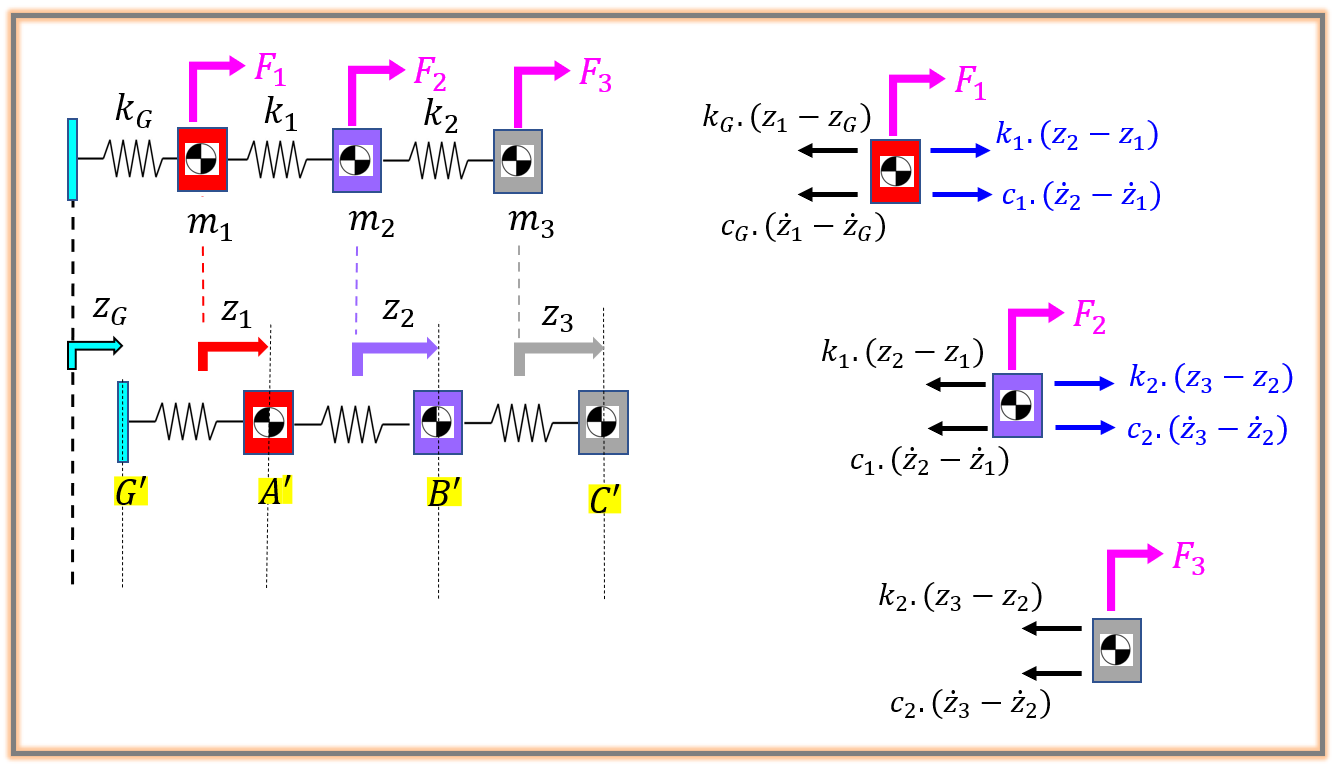

Consult database for parameters :

- See: [` bh_smd_3dof_tmd_params_CLS.m `](matlab:  open  bh_smd_3dof_tmd_params_CLS.m)

- See:   [`bh_smd_3dof_tmd_params_database.xlsx`](matlab:  winopen bh_smd_3dof_tmd_params_database.xlsx)

% param_DB = bh_smd_3dof_tmd_params_CLS();
% param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_2");
% param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_3");
param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_FLEX");

Masses:

params_T.m1 = param_DB.m1;  % (kg)
params_T.m2 = param_DB.m2;  % (kg)
params_T.m3 = param_DB.m3;  % (kg)

params_T.ma = param_DB.ma;  % (kg)
params_T.mb = param_DB.mb;  % (kg)
params_T.mc = param_DB.mc;  % (kg)

Spring Stiffness - PRIMARY only:

params_T.k1 = param_DB.k1;  % (N/m)
params_T.k2 = param_DB.k2;  % (N/m)
params_T.kG = param_DB.kG;  % (N/m)

## Solve for the UNdamped **BASELINE** case - i.e.:  no TMDs

- So without the TMD's what are the natural undamped frequencies of the system 

- See [`bh_newton_smd_3dof_eig.mlx`](matlab:  edit bh_newton_smd_3dof_eig.mlx)

[w2_baseline_list, eVec_PHI_base] = bh_newton_smd_3dof_eig(  params_T.m1, params_T.m2, params_T.m3, ...
                                                             params_T.kG, params_T.k1, params_T.k2 );
w_baseline = sqrt(w2_baseline_list) % (rad/sec)

w_baseline =     6.9531
   19.4822
   28.1526


So what do the mode shapes look like ? - which dof exhibit the largest displacements for a given resonance ?

- ***NOTE:***  the **mode shapes** are the COLUMNS of the heatmap shown below

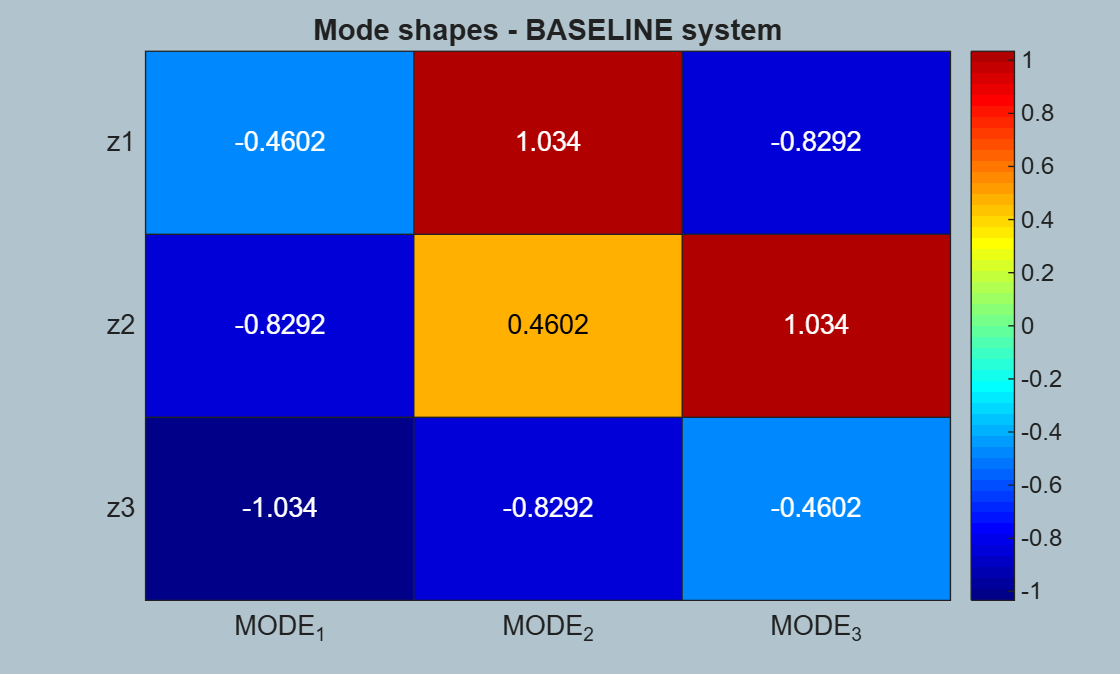

figure;
    heatmap( ("MODE_"+[1:3]), ["z1","z2","z3"], eVec_PHI_base, "Colormap", jet(50)  );  title("Mode shapes - BASELINE system");

 **Pause and Ponder.**  So it appears that:

- $\omega_1$  causes $z_3$ to have the largest displacement

- $\omega_2$  causes $z_1$ to have the largest displacement

- $\omega_3$  causes $z_2$ to have the largest displacement

So ? - So when we design the Tuned Mass Dampers (TMDs) a design strategy could be:

- to attenuate $\omega_1$ consider a TMD that strongly influences $z_3$     ${\Longrightarrow \;\;k}_c =m_c \ldotp \omega_1^2$

- to attenuate $\omega_2$ consider a TMD that strongly influences $z_1$     ${\Longrightarrow \;\;k}_a =m_a \ldotp \omega_2^2$

- to attenuate $\omega_3$ consider a TMD that strongly influences $z_2$     ${\Longrightarrow \;\;k}_b =m_b \ldotp \omega_3^2$

### What do the FRFs look like for theUNdamped BASELINE system (i.e. NO TMDs) 

Create the Mechanical system matrices

- See [`bh_newton_smd_3dof_model_MCK.mlx`](matlab:  open bh_newton_smd_3dof_model_MCK.mlx)

-  NOTE:  we're setting all **damping coefficients to ZERO** ... so it's the **UNDAMPED** system

[M_base, C_base, K_base, ~] = bh_newton_smd_3dof_model_MCK(  params_T.m1, params_T.m2, params_T.m3, ...
                                                         params_T.kG, params_T.k1, params_T.k2,  "DAMPING_C", [0,0,0] );

whos M_base C_base  K_base

  Name        Size            Bytes  Class     Attributes

  C_base      3x3                72  double              
  K_base      3x3                72  double              
  M_base      3x3                72  double              



Create the State Space model

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.f$

- $y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

A = [   -inv(M_base)*C_base,    -inv(M_base)*K_base;  
        eye(size(M_base,1)),    zeros(size(M_base,1))    ];
B = [inv(M_base);zeros(size(M_base,1))];
G = [zeros(size(M_base,1)), eye( size(M_base,1) )];
D = zeros( size(M_base,1) );

H_base_mat = ss(A,B,G,D,0,"Outputname",["z1","z2","z3"],"InputName",["f1g+f1","f2","f3"]);

whos H_base_mat

  Name            Size            Bytes  Class    Attributes

  H_base_mat      3x3              2513  ss                 



Plot the FRFs where the input is $u={\left(F_1 \right)}_{\mathrm{TOTAL}} \;$

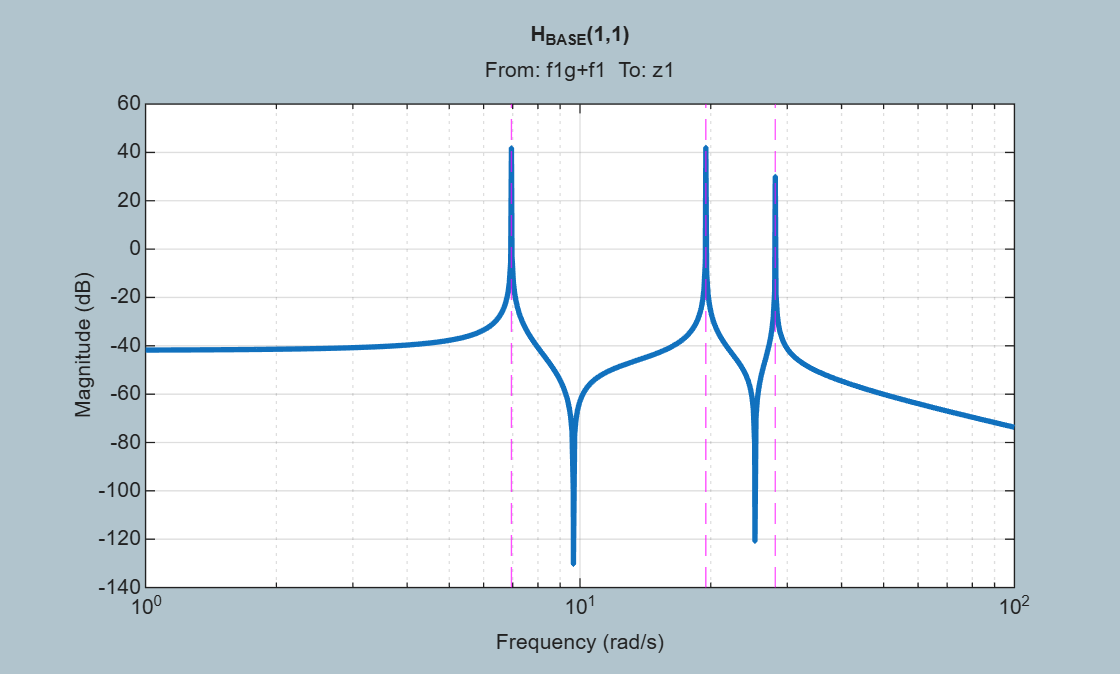

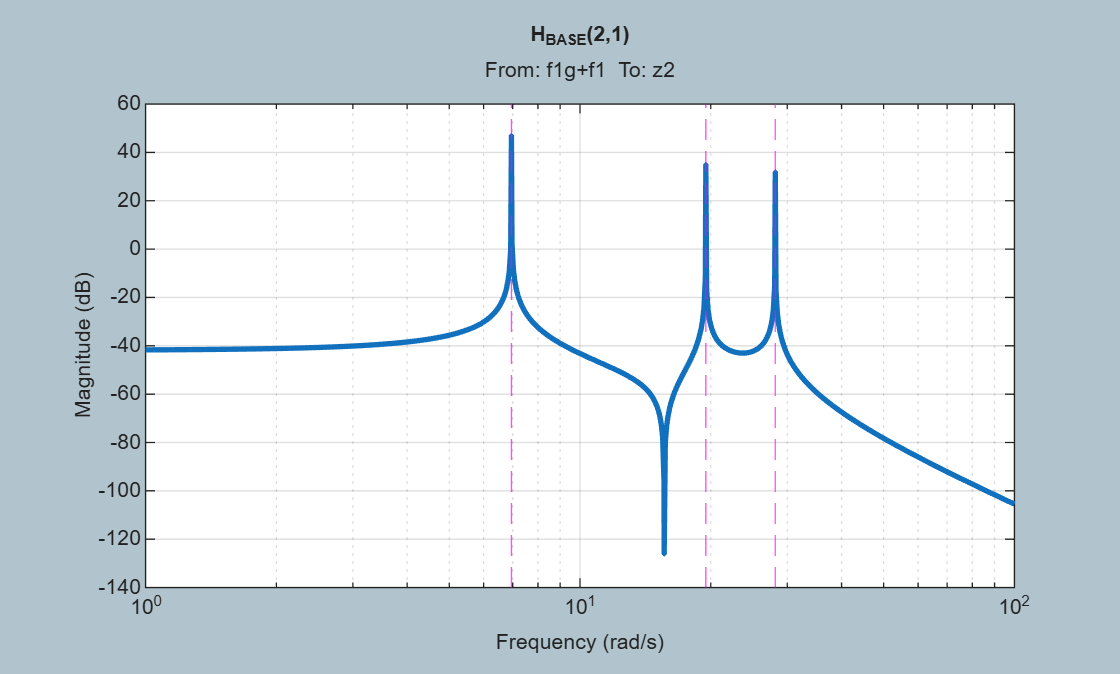

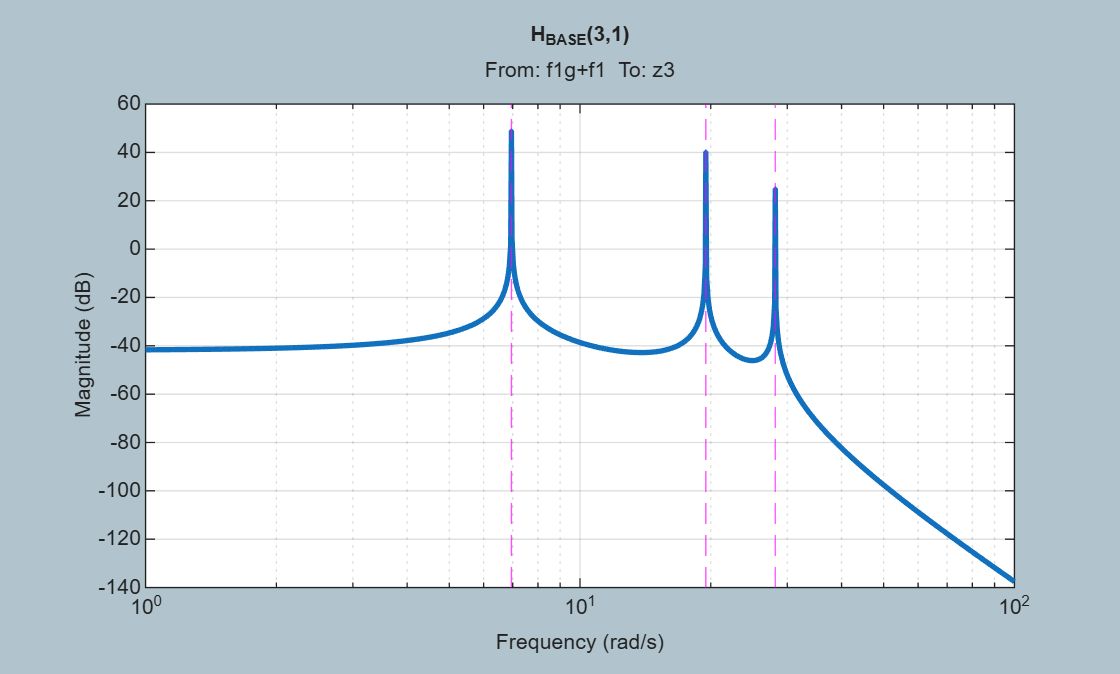

w_list_for_bode = [1:0.001:100];
bd_opts =  bodeoptions();
bd_opts.PhaseVisible="off";
for kk=1:3
    figure;
        bp = bodeplot(H_base_mat(kk,1), w_list_for_bode, bd_opts);
            bp.Responses(1).LineWidth = 2;
            grid on
            title("H_{BASE}("+kk+",1)", FontWeight="bold")    
        
        % plot the UNdamped Natural frequencies from our MODAL analysis in pink
        hold on
            xline(w_baseline, "--m")
end

## Clean up

clear A B G D H_base_mat

# Consider a NUMERIC example - **Part 2:   the MTMD system**

Now let's explore the FRFs of our MTMD system:

## Recall the undamped BASELINE system Resonances

Firstly let's recall the resonant frequencies of our BASELINE undamped 3-dof system:

w_baseline  %  (rad/sec)

w_baseline =     6.9531
   19.4822
   28.1526


## Create the MTMD system

Consider a design based on our earlier observations, i.e.:

- to attenuate $\omega_1$ consider a TMD that strongly influences $z_3$     ${\Longrightarrow \;\;k}_c =m_c \ldotp \omega_1^2$

- to attenuate $\omega_2$ consider a TMD that strongly influences $z_1$     ${\Longrightarrow \;\;k}_a =m_a \ldotp \omega_2^2$

- to attenuate $\omega_3$ consider a TMD that strongly influences $z_2$     ${\Longrightarrow \;\;k}_b =m_b \ldotp \omega_3^2$

params_T.ka = params_T.ma * w2_baseline_list(2);   % (N/m)
params_T.kb = params_T.mb * w2_baseline_list(3);   % (N/m)
params_T.kc = params_T.mc * w2_baseline_list(1);   % (N/m)
%---------------------------------------------------------------
% params_T.ka = params_T.ma * w2_baseline_list(1);   % (N/m)
% params_T.kb = params_T.mb * w2_baseline_list(2);   % (N/m)
% params_T.kc = params_T.mc * w2_baseline_list(3);   % (N/m)

## So the MASS and STIFFNESS matrices are:

We'll now create Numeric matrices for the MTMD configured system. Recall our previously derived SYMBOLIC matrices

whos M_full K_full

  Name        Size            Bytes  Class    Attributes

  K_full      6x6                 8  sym                
  M_full      6x6                 8  sym                



Now substitute numeric values for the symbolic symbols

LIST_sym_vars = [m_1, m_2, m_3, m_a, m_b, m_c,  ...
                 k_g, k_1, k_2, k_a, k_b, k_c];
LIST_values   = [params_T.m1, params_T.m2, params_T.m3, params_T.ma, params_T.mb, params_T.mc, ...
                 params_T.kG, params_T.k1, params_T.k2, params_T.ka, params_T.kb, params_T.kc];

M_val = double(  subs(M_full, LIST_sym_vars, LIST_values)   );
K_val = double(  subs(K_full, LIST_sym_vars, LIST_values)   );

## Damping matrix:

And define the Damping matrix too

BETA_CONST_PROP_DAMPING = 1e-3; %1e-4; %0; %1e-3;
C_val = BETA_CONST_PROP_DAMPING * K_val;

### Modal Analysis of TMD system:

- $M\ldotp \ddot{X} \;+\;K\ldotp X\;=0$  where $X\;\in R^{\;N\times 1}$

- see the function [`bh_do_modal_analysis()`](matlab:  open bh_do_modal_analysis)

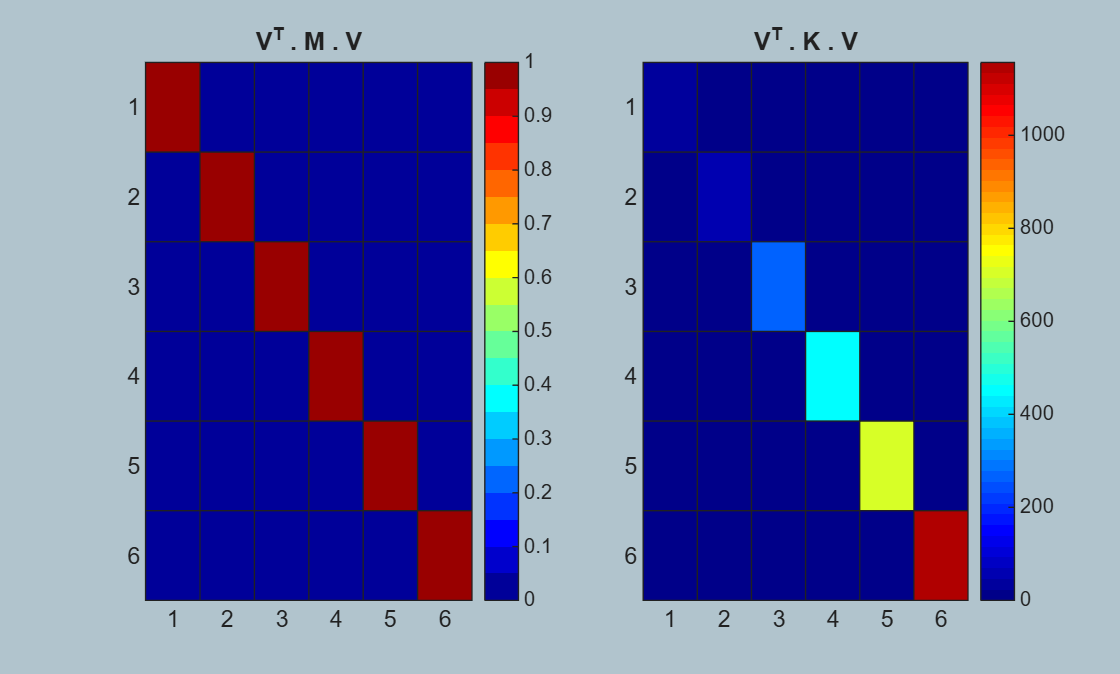

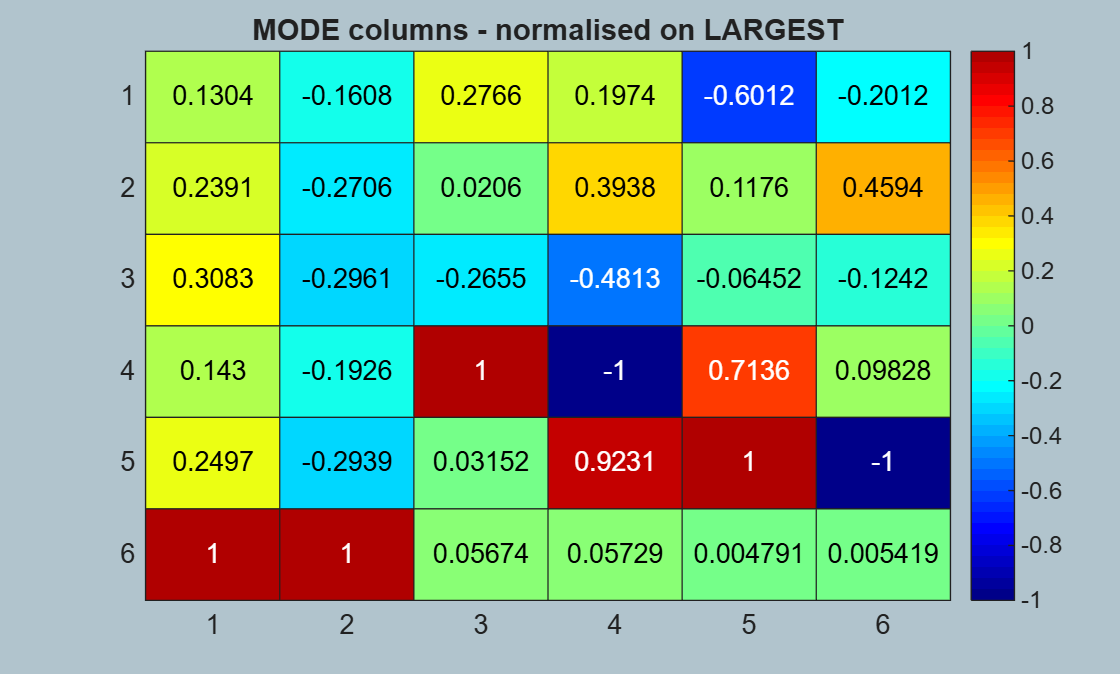

[eVec_PHI, w_list, w_table] = bh_do_modal_analysis( M_val, K_val, tf_do_plots=true );

#### Great, so let's summarize what we have. 

Our Undamped Natural frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\mathrm{rad}}{\sec }\right\rbrack$:

w_table 

w_table = 6×2 table
    w_radpersec     f_Hz  
    ___________    _______

      5.7827       0.92035
      7.9159        1.2599
       16.57        2.6373
      21.318        3.3929
      26.445        4.2089
       34.01        5.4129

	Get insights using Copilot


And our Mass matrix normalized MODE shapes are the columns of the matrix:

eVec_PHI

eVec_PHI =     0.2959   -0.3533    0.6606    0.3114   -1.0255   -0.4137
    0.5425   -0.5945    0.0492    0.6213    0.2006    0.9445
    0.6995   -0.6505   -0.6342   -0.7593   -0.1101   -0.2554
    0.3245   -0.4231    2.3883   -1.5777    1.2172    0.2020
    0.5664   -0.6455    0.0753    1.4563    1.7057   -2.0558
    2.2689    2.1967    0.1355    0.0904    0.0082    0.0111


## State Space and Transfer Functions  - MTMD system

Recall that for the Damped Mechanical system, we have:

- $M\ldotp \ddot{x} \;+C\ldotp \dot{x} \;+\;\;K\ldotp x=F$  where $X\;\in R^{\;P\times 1}$

Taking the Laplace transform AND assuming zero initial conditions, we have

- 
$$\left\lbrack M\ldotp s^2 \;\;+\;\;C\ldotp s\;+\;\;K\right\rbrack \ldotp X\left(s\right)\;=F\left(s\right)$$


-             
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;X\left(s\right)\;={\left\lbrack M\ldotp s^2 \;+\;C\ldotp s\;+\;\;K\right\rbrack }^{-1} \ldotp F\left(s\right)$$


-                            
$$X\left(s\right)=H\left(s\right)\ldotp F\left(s\right)$$


Similarly in State Space form we have:

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.F$

- $y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

NUM_DOF = size(M_val,1);

A = [   -inv(M_val)*C_val,  -inv(M_val)*K_val;  
         eye(NUM_DOF),                  zeros(NUM_DOF)    ];
B = [inv(M_val);zeros(NUM_DOF)];
G = [zeros(NUM_DOF), eye(NUM_DOF)];
D = zeros(NUM_DOF);

H_mat_val = ss(A,B,G,D,0,"Outputname",["z1","z2","z3",  "za","zb","zc"],"InputName",["f1","f2","f3","fa","fb","fc"]);
    
whos H_mat_val

  Name           Size            Bytes  Class    Attributes

  H_mat_val      6x6              4973  ss                 



### What are the system poles ?

damp(H_mat_val) 

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.67e-02 + 5.78e+00i     2.89e-03       5.78e+00         5.98e+01    
 -1.67e-02 - 5.78e+00i     2.89e-03       5.78e+00         5.98e+01    
 -3.13e-02 + 7.92e+00i     3.96e-03       7.92e+00         3.19e+01    
 -3.13e-02 - 7.92e+00i     3.96e-03       7.92e+00         3.19e+01    
 -1.37e-01 + 1.66e+01i     8.29e-03       1.66e+01         7.28e+00    
 -1.37e-01 - 1.66e+01i     8.29e-03       1.66e+01         7.28e+00    
 -2.27e-01 + 2.13e+01i     1.07e-02       2.13e+01         4.40e+00    
 -2.27e-01 - 2.13e+01i     1.07e-02       2.13e+01         4.40e+00    
 -3.50e-01 + 2.64e+01i     1.32e-02       2.64e+01         2.86e+00    
 -3.50e-01 - 2.64e+01i     1.32e-02       2.64e+01         2.86e

### Explore the Transfer Functions associated with the input $u={\left(F_1 \right)}_{\mathrm{TOTAL}} \;$

For the 3 transfer functions - $H_{11}$, $H_{21}$ , $H_{31}$:

Compute their zeros(ANTI resonances) and keep just the positive imag parts

for kk=1:3

  THE_H = H_mat_val(kk,1);
  fprintf("\n %s", repmat('-',1,50));
  fprintf("\n H(%d,1):",kk);
  
  % compute POLES 
  tmp = pole(THE_H);
  tmp = tmp(  imag(tmp) > 0 );
  tmp = sort(imag(tmp));

  fprintf("\n     POLES(imag parts): ---> ");  
  display(tmp(:)')

  % compute ZEROS
  tmp = zero(THE_H);
  tmp = tmp(  imag(tmp) > 0 );
  tmp = sort(imag(tmp));

  fprintf("\n     ZEROS(imag parts): ---> ");
  display(tmp(:)')
end


 --------------------------------------------------


 H(1,1):


     POLES(imag parts): ---> 

    5.7827    7.9159   16.5699   21.3170   26.4428   34.0055




     ZEROS(imag parts): ---> 

    6.4977    9.9876   19.4813   22.1260   33.2691




 --------------------------------------------------


 H(2,1):


     POLES(imag parts): ---> 

    5.7827    7.9159   16.5699   21.3170   26.4428   34.0055




     ZEROS(imag parts): ---> 

    6.7917   15.9941   19.4813   28.1498




 --------------------------------------------------


 H(3,1):


     POLES(imag parts): ---> 

    5.7827    7.9159   16.5699   21.3170   26.4428   34.0055




     ZEROS(imag parts): ---> 

    0.0001    6.9531   19.4813   28.1498



So ... do these ANTIRESONANCES really correspond to the POLES of the baseline system ?

w_baseline.'

ans =     6.9531   19.4822   28.1526


Plot some BODE plots

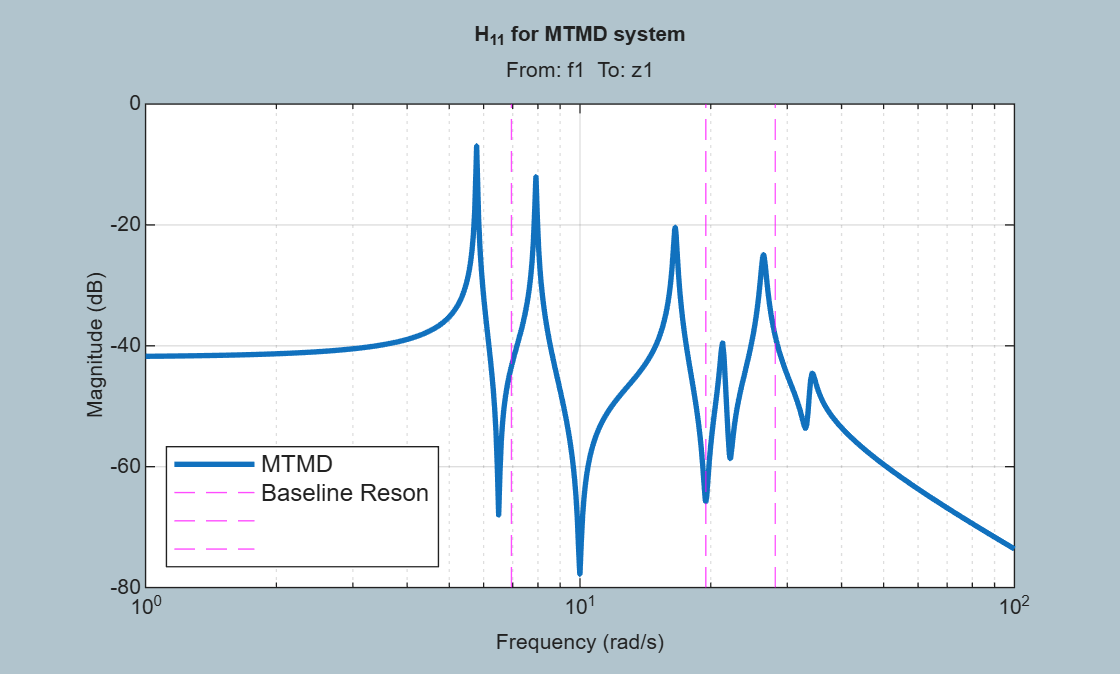

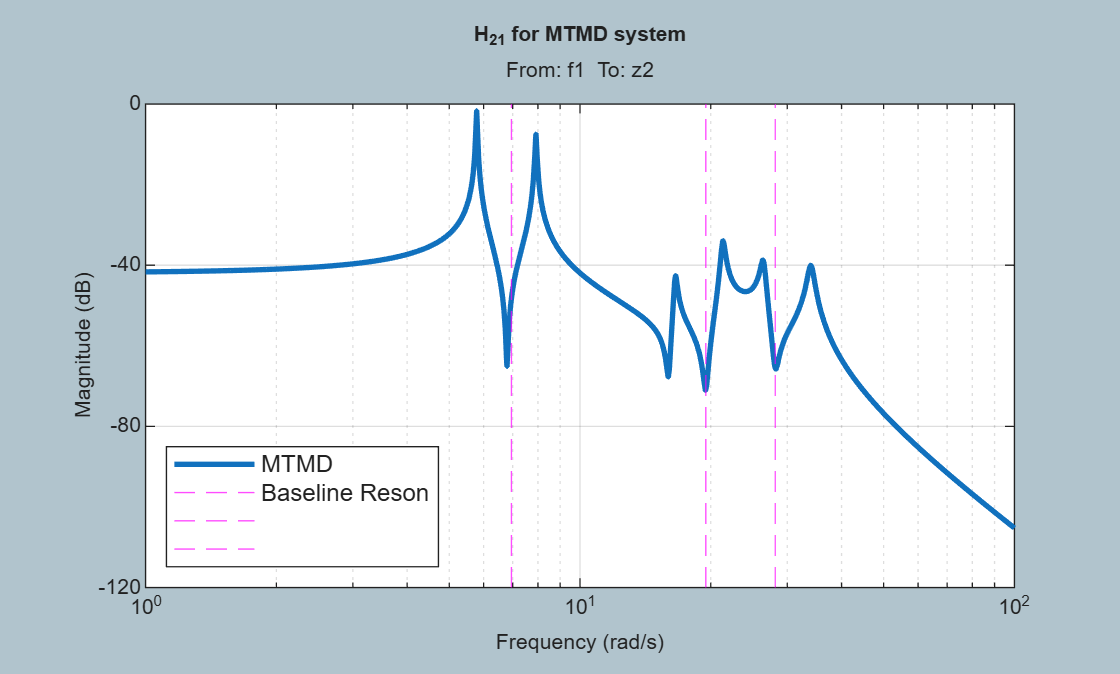

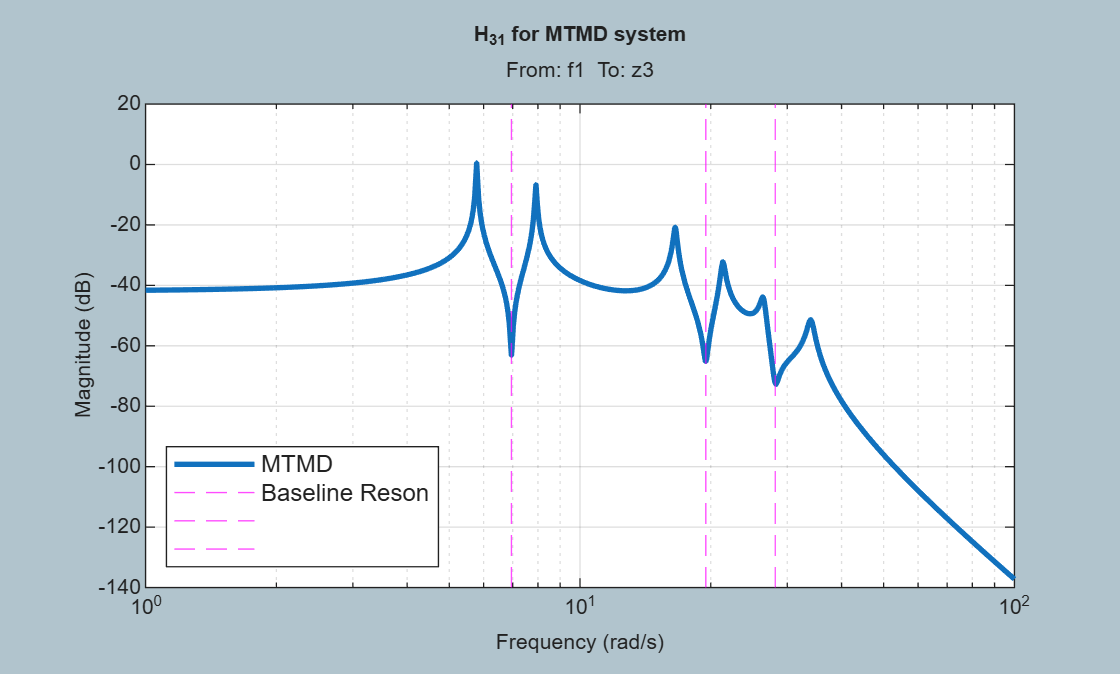

w_list_for_bode = [1:0.001:100];
bd_opts =  bodeoptions();
bd_opts.PhaseVisible="off";


for kk=1:3
    figure;
        bp = bodeplot(H_mat_val(kk,1), w_list_for_bode, bd_opts);
            bp.Responses(1).LineWidth = 2;
            grid on
            title("H_{"+kk+"1} for MTMD system", FontWeight="bold")    
           
         % plot the BASELINE system UNdamped Natural frequencies from our MODAL analysis in pink
         hold on
            xline(w_baseline, "--m")
         legend(["MTMD", "Baseline Reson"], "Location", "southwest")   
         drawnow
end

## Let's Simulate 

Let's simulate our TMD system being excited at the baseline natural frequencies.

- We'll apply the excitation to $m_1$

Recall we designed our Tuned Mass Dampers to

- attenuate $\omega_1$ by tuning a TMD that strongly influences $z_3$     ${\Longrightarrow \;\;k}_c =m_c \ldotp \omega_1^2$

- attenuate $\omega_2$ by tuning a TMD that strongly influences $z_1$     ${\Longrightarrow \;\;k}_a =m_a \ldotp \omega_2^2$

- attenuate $\omega_3$ by tuning a TMD that strongly influences $z_2$     ${\Longrightarrow \;\;k}_b =m_b \ldotp \omega_3^2$

What frequency should we shake $m_1$ at?

w_exci_req = w_baseline(1);

Simulate via [`lsim()`](matlab: doc lsim)

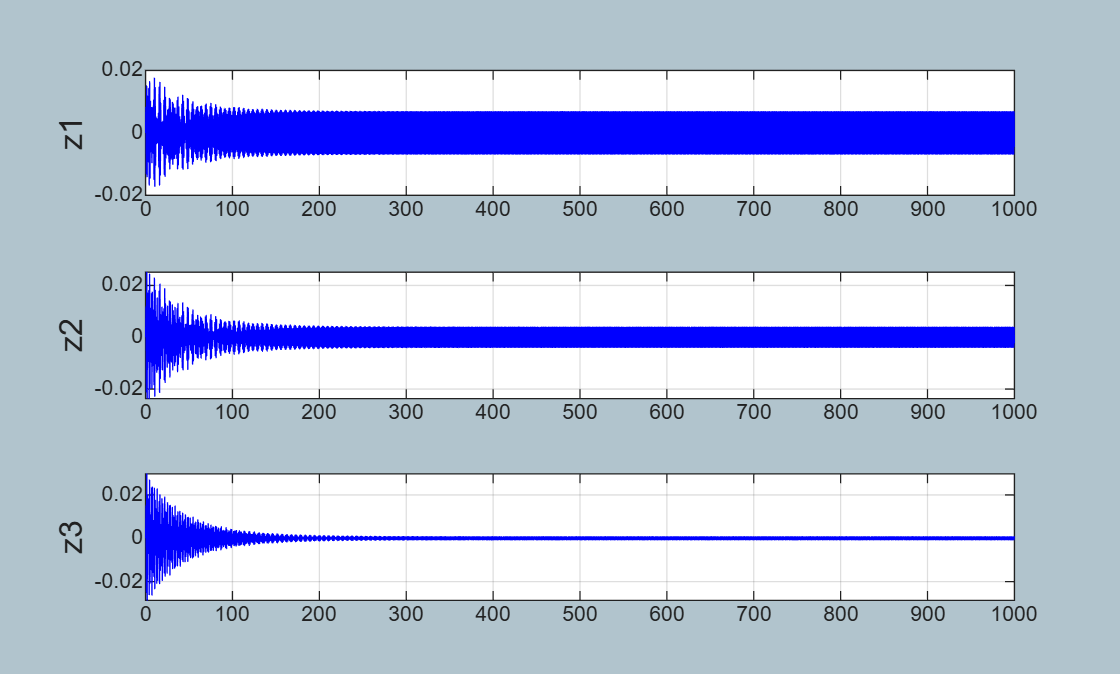

t_col = [0:0.001:1000]';
u_mat = [  1*sin(w_exci_req*t_col),  zeros(length(t_col),5)  ];

y_mat = lsim(H_mat_val, u_mat, t_col);

figure;
    subplot(3,1,1);  plot(t_col, y_mat(:,1), '-b');  grid on;  ylabel("z1", FontSize=12); 
    subplot(3,1,2);  plot(t_col, y_mat(:,2), '-b');  grid on;  ylabel("z2", FontSize=12); 
    subplot(3,1,3);  plot(t_col, y_mat(:,3), '-b');  grid on;  ylabel("z3", FontSize=12);     

 PAUSE and PONDER:

- When we excited $m_1$ @ $\omega_1$ ... did you see significant attenuation at $z_3$ ?

- When we excited $m_1$ @ $\omega_2$ ... did you see significant attenuation at $z_1$ ?

- When we excited $m_1$ @ $\omega_3$ ... did you see significant attenuation at $z_2$ ?